clear %clear workspace

%initialize pins for matlab
sensor_pin = 'A5';
pan_pin = 'D9';
tilt_pin = 'D10';

% initialize arduino connection
a = arduino('COM10', 'Uno', 'Libraries', 'Servo');
% initialize servo object (matlab toolbox for arduino)
pan_servo = servo(a,pan_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);
tilt_servo = servo(a,tilt_pin,"MinPulseDuration",700*10^-6,'MaxPulseDuration',2300*10^-6);

%move servo to initial position for next scan
writePosition(pan_servo,Deg2Pos(0));
writePosition(tilt_servo,Deg2Pos(0));

%start the scan
%pattern: Line by line: start from upper left corner, perform horizontal scan
points = []; %initialize a matrix to store angle and distance information
for tilt_angle = -15:2:50
    % the tilt servo only steps when a horizontal scan is completed
    writePosition(tilt_servo,Deg2Pos(tilt_angle));
    pause(0.1);
    for pan_angle = -30:2:30
        % measure the distance everytime the pan servo moves
        writePosition(pan_servo,Deg2Pos(pan_angle));
        points= [points,get_coordinates(a,pan_angle,tilt_angle)];
        pause(0.1);
    end
end

   -15



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -13



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



   -11



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -9



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -7



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -5



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -3



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    -1



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     1



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     3



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     5



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     7



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



     9



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    11



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    13



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    15



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    17



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    19



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    21



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    23



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    25



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    27



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    29



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    31



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    33



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    35



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    37



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    39



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    41



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    43



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    45



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    47



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



    49



   -30

   -28

   -26

   -24

   -22

   -20

   -18

   -16

   -14

   -12

   -10

    -8

    -6

    -4

    -2

     0

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20

    22

    24

    26

    28

    30



%load data from the saved matrix
x = points(1,:);
y = points(2,:);
z = points(3,:);

%make a heat plot
pointsize = 10;
scatter(x, y, pointsize, z)

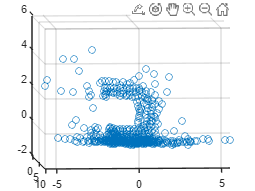

%% DO NOT TOUCH

clf
x = points(1,:);
x = x(z<10);
y = points(2,:);
y = y(z<10);
z = points(3,:);
z = z(z<10);
scatter3(x,z,y)

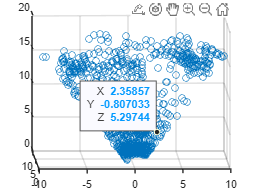

clf
x = points(1,:);
y = points(2,:);
z = points(3,:);
scatter3(x,y,z)

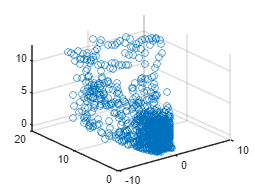

%% TOUCH
clf
z = points(3,:);
%z = z(z<15);
x = points(1,:);
%x = x(z<15);
y = points(2,:);
%y = y(z<15);
scatter3(x,z,y)

disp(points);



function pos = Deg2Pos(degree)
% degree ranges from -90 to 90
pos = 0.5-degree/180; %fixed, from left to right, up to down
end

function distance = get_distance(voltage)
distance = 18.9*exp(-0.7578*voltage);
end 
